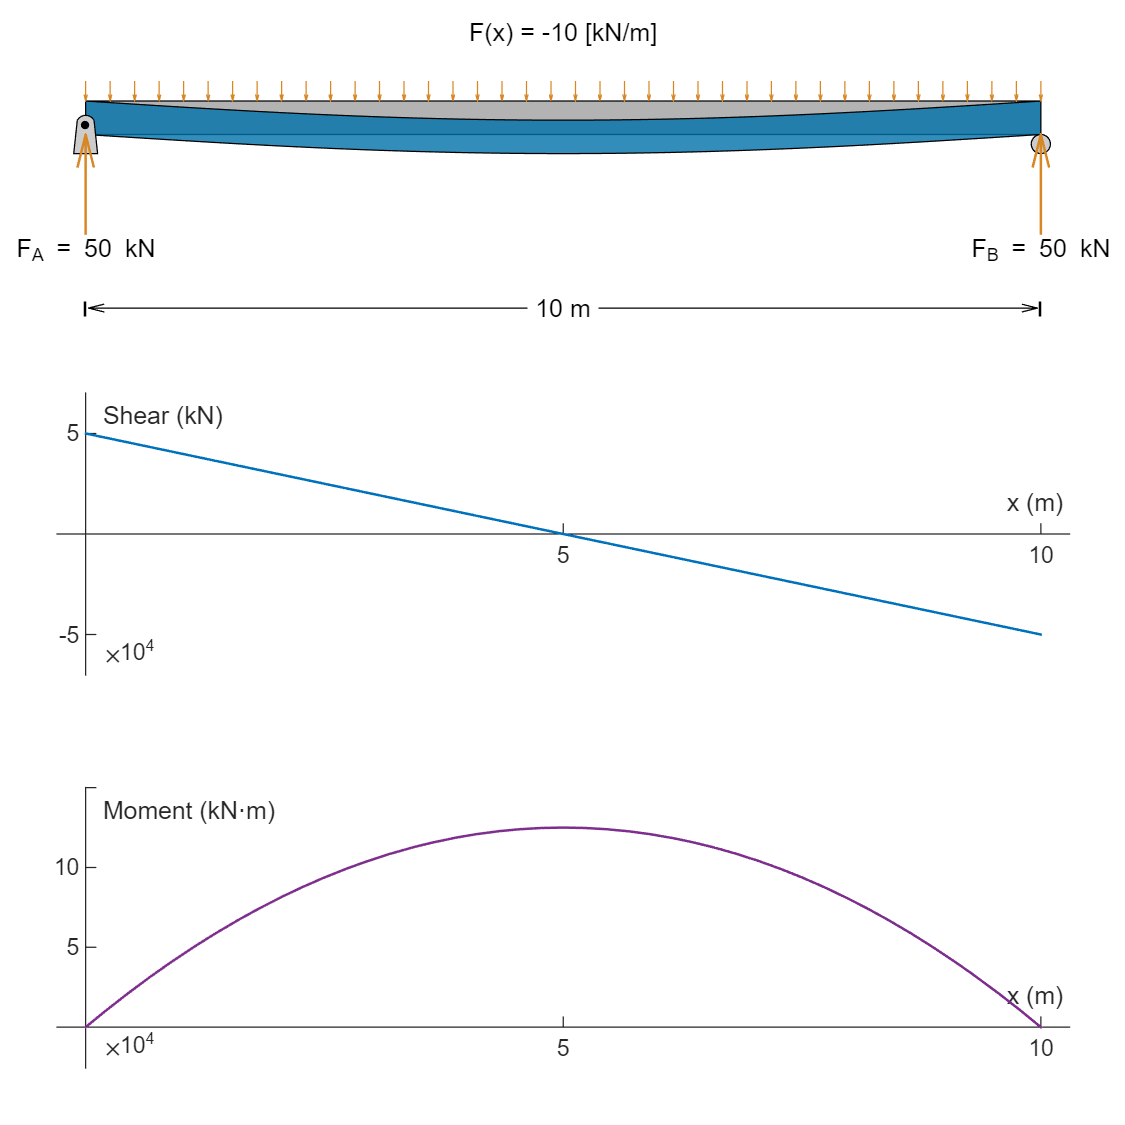

$$v(x) = -\frac{x\,\left(x^{3}-20\,x^{2}+1000\right)}{15625}$$

syms x
wfunc = -1; % Distributed force function (unitless)
wmag = 10*1e3; % Magnitude of the distributed force (N)
E = 20*1e9; % Young's modulus (Pa)
L = 10; % Beam length (m)
b = 0.25; % Beam width (m)
h = 0.25; % Beam height (m)
w = sym(wfunc*wmag);
v(x) = deflDiagramSupp(w,E,L,b,h)

**Helper Functions**

function vsol = deflDiagramSupp(w,E,L,b,h)

    %%%% Calculations
    % Moment function
    syms x F_A F_B u v(x)
    w(x) = w;
    eqF = F_A + F_B + int(w(x),x,0,L) == 0;
    eqM = L*F_B + int(w(x)*x,x,0,L) == 0;
    sol = solve([eqF,eqM],[F_A,F_B]);
    FA = sol.F_A;
    FB = sol.F_B;
    S(x) = FA + int(w(u),u,0,x);
    M(x) = int(S(u),u,0,x);

    % Area moment of inertia
    I = sym(b)*sym(h)^3/12;
    
    % Solve for the deflection 
    deq = diff(v,x,2) == M(x)/(E*I);
    bc = [v(0) == 0, v(L) == 0];
    vsol(x) = dsolve(deq,bc);
    
    %%% Figure
    % Build the figure
    figure("Position",[0 0 600 600])
    
    % Bar diagram
    subplot("Position",[0.05,0.7,0.9,0.25])
    
    % Bar diagram
    rollerPos = L;
    pinPos = 0;
    xLims = barDiagramDefl(L,double(FA)/1e3,double(FB)/1e3,w(x)/1e3,rollerPos,pinPos,vsol);
    
    % Shear diagram
    subplot("Position",[0.05,0.4,0.9,0.25])
    shearDiagram(L,xLims,S(x))
    
    % Moment diagram
    subplot("Position",[0.05,0.05,0.9,0.25])
    momentDiagram(L,xLims,M(x))
end

function xLims = barDiagramDefl(length,FA,FB,FappliedSym,rollerPos,pinPos,vsol)
    % Deformation
    xvec = linspace(0,length,300);
    wvec = double(vsol(xvec));
    barHeight = 0.35;
    defAlpha = 0.8;
    defColor = [0 113 170]/255;
    barxdef = [xvec,xvec(end:-1:1)]';
    barydef = [wvec+barHeight,wvec(end:-1:1)]';

    % Force arrow calculations
    maxLength = 10;
    xApplied = linspace(0,maxLength,40);
    Fapplied = double(subs(FappliedSym,xApplied));

    % Settings
    barColor = [0.7 0.7 0.7];
    supportColor = [0.8 0.8 0.8];
    reactionColor = [215 136 37]/255;
    appliedColor = [215 136 37]/255;
    barHeight = 0.35;
    offsetx = 0.0;
    rCirc = 0.1;
    pinHeight = 0.1;
    quiverLW = 1;
    
    circCenter = [rollerPos,-rCirc]; % (xc,yc)
    pinCenter = [pinPos,pinHeight];
    diagramAxisLims = [-rCirc*3,maxLength+rCirc*3,-barHeight,barHeight*2];
    xLims = diagramAxisLims(1:2);
    
    % Bar
    barx = [-offsetx, length+offsetx, length+offsetx, -offsetx];
    bary = [0 0 barHeight barHeight];
    patch(barx,bary,barColor)
    hold on
    % Deformed bar
    patch(barxdef,barydef,defColor,"FaceAlpha",defAlpha)

    % Pin support
    theta = linspace(pi-0.5,0+0.5,50);
    xSupport = rCirc*cos(theta) + pinCenter(1);
    ySupport = rCirc*sin(theta) + pinCenter(2);
    xSupport = [pinPos-0.125, xSupport,pinPos+rCirc*2-0.075];
    ySupport = [-2*rCirc, ySupport, -2*rCirc];
    patch(xSupport,ySupport,supportColor)
    plot(pinCenter(1),pinCenter(2),"k.","MarkerSize",10)

    % Circle (roller support)
    theta = linspace(0,2*pi,50);
    xcirc = rCirc*cos(theta) + circCenter(1);
    ycirc = rCirc*sin(theta) + circCenter(2);
    patch(xcirc,ycirc,supportColor);    

    % Force scaling
    Fscale = 3*barHeight/max(abs([FA,FB,Fapplied]));

    % Applied force arrow(s)
    vApplied = Fapplied*Fscale;
    yApplied = xApplied*0+barHeight-(vApplied<0).*vApplied;
    idx = xApplied <= length;
    xApplied = xApplied(idx);
    vApplied = vApplied(idx);
    yApplied = yApplied(idx);
    xText = mean(xApplied.*abs(vApplied))./mean(abs(vApplied));
    quiver(xApplied,yApplied,xApplied*0,vApplied,"Color",appliedColor,"Autoscale","off")

    % Reaction force arrows
    xr = [pinPos, rollerPos];
    vr = [FA*Fscale, FB*Fscale];
    yr = -vr + vr.*(vr < 0);
    quiver(xr,yr,xr*0,vr,"Color",reactionColor,"AutoScale","off",...
            "LineWidth",quiverLW)
    yrText = -abs(vr);
    text(xr,yrText,["F_A = " + num2str(FA,3) + " kN","F_B = " + num2str(FB,3) + " kN"],...
        "HorizontalAlignment","center","VerticalAlignment","top")

    axis(diagramAxisLims)
    axis equal
    axis off

    ax = gca;
    ax.Clipping = "off";

    yAxLims = get(gca,"ylim");
    labelPosY = yAxLims(1) - rCirc;
    % Length label
    xs = sort([0 pinPos rollerPos length]);
    plot(xs,ones(1,4)*labelPosY,"k|","LineWidth",1)
    for k = 1:(numel(xs)-1)
        if(abs(diff(xs(k:k+1)))>0)
            xvals = xs(k:k+1) + [0.03,-0.035];
            mx = mean(xvals);
            quiver([mx,mx],[1 1]*labelPosY,[xvals(1)-mx,xvals(2)-mx],[0 0],"k","Autoscale","Off","MaxHeadSize",0.5/diff(xvals))
            text(mean(xvals),labelPosY,num2str(diff(xs(k:k+1))) + " m","BackgroundColor","white",...
                "HorizontalAlignment","center","VerticalAlignment","middle")
        end
    end

    text(xText,yAxLims(2),"F(x) = " + string(FappliedSym) +" [kN/m]",...
        "HorizontalAlignment","center","VerticalAlignment","top")
    hold off
    
end

function shearDiagram(length,xLims,shearForce)

    % Settings
    shearLW = 1;

    % Plot
    fp = fplot(shearForce,[0-1e-2,length+1e-2],"LineWidth",shearLW);
    yLims = minmax(fp.YData);
    
    xlabel("x (m)")
    ylabel("Shear (kN)")
    xlim(xLims)
    if(~all(yLims == 0))
        ylim([yLims(1)-diff(yLims)*0.2,yLims(2)+diff(yLims)*0.2])
    end
    xticks([0,length/2,length])
    box off
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    ax.Clipping = "off";
end

function momentDiagram(length,xLims,moment)

    % Settings
    lw = 1;
    color = [0.4940    0.1840    0.5560];

    % Plot
    fp = fplot(moment,[0-1e-2,length+1e-2],"LineWidth",lw,"Color",color);
    yLims = minmax(fp.YData);
    
    xlabel("x (m)")
    ylabel("Moment (kN·m)")
    xlim(xLims)
    if(~all(yLims == 0))
        ylim([yLims(1)-diff(yLims)*0.2,yLims(2)+diff(yLims)*0.2])
    end
    xticks([0,length/2,length])
    box off
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    ax.Clipping = "off";
    
end 